rf_raw = load('rf_data/rf_ln15.mat')

rf_raw = struct with fields:
    rf_data: [6096×1 double]
     tstart: 3.6260e-05


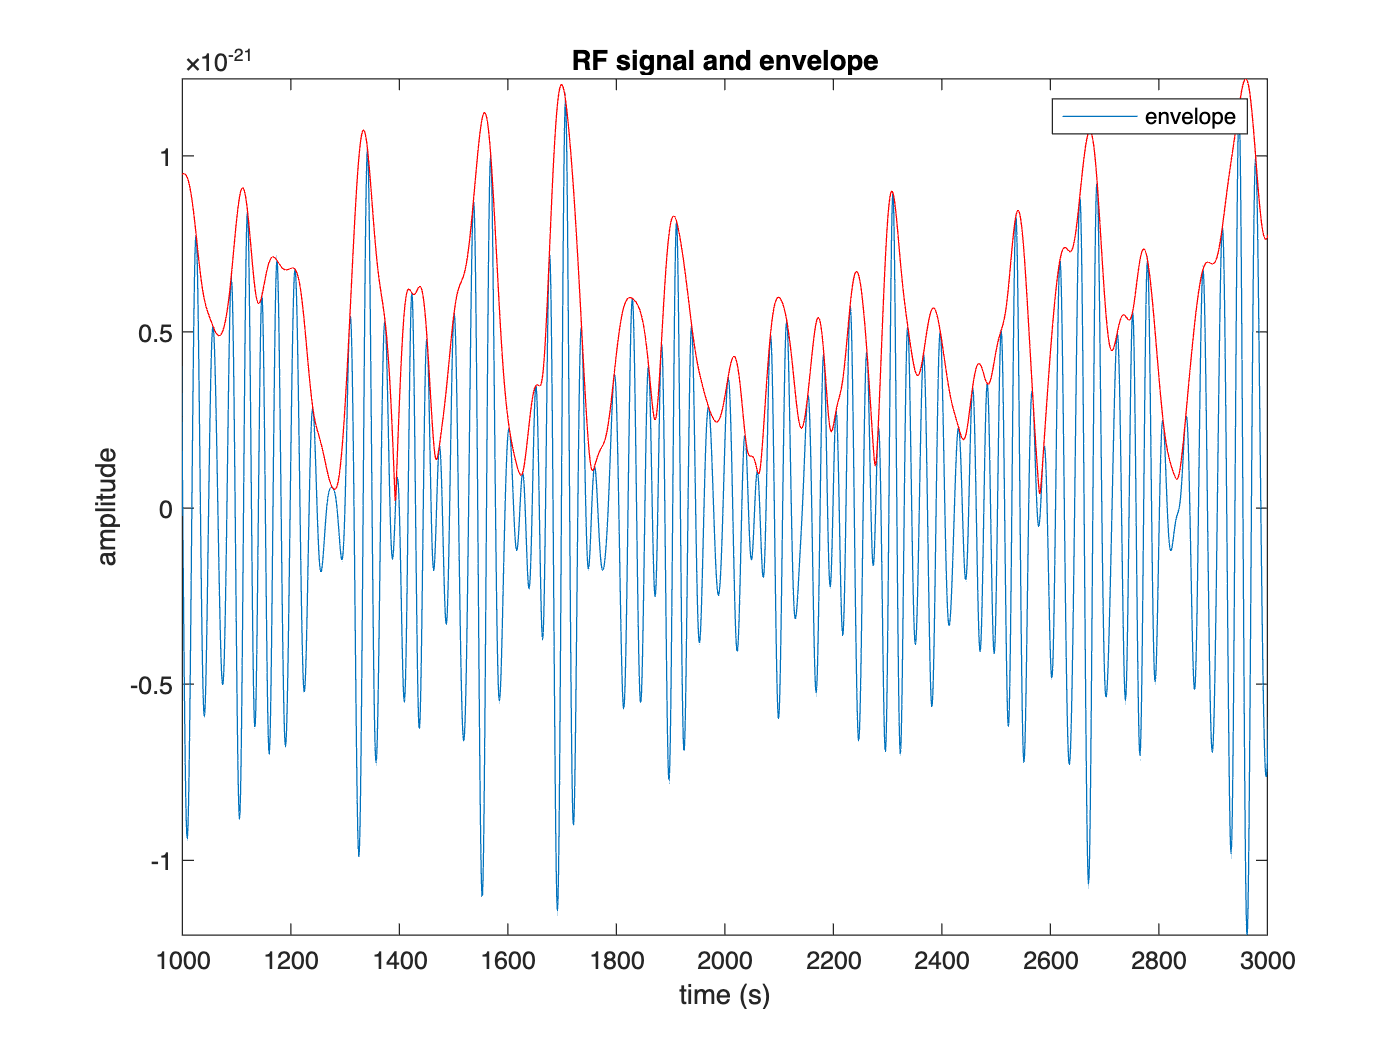

rf_env = rf_raw.rf_data;
env = abs(hilbert(rf_env));

figure(1)

plot(rf_env)
title('RF signal and envelope')
legend('raw signal')
ylabel('amplitude')
xlabel('time (s)')
xlim([1000 3000])
axis tight

hold on

plot(env,'-r')
xlim([1000 3000])
legend('envelope')